% Part B
% Setting variables
Fs = 16000;
nBits = 16;
nChannels = 1;

% Create recording object
recObj = audiorecorder(Fs,  nBits, nChannels);

% Start recording
record(recObj);

% Stop recording
record(recObj);

pause

% Retrieving audio data
audioData = getaudiodata(recObj);

% Writing audio file
audiowrite("Firstname_Lastname.wav", audioData, Fs); 

% Repeat of Part A
[x, F] = audioread("C:\Users\josh2\OneDrive\Documents\BU_ENGEC516\Assignment 1\Processing\Firstname_Lastname.wav");

% Compute duration of audio
duration = length(x) / F

duration = 34.4640

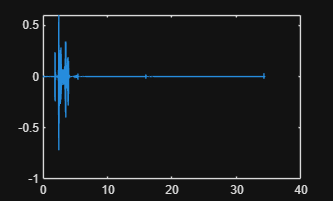


% Create time axis in seconds
t = (0:length(x)-1)/F;

% Plot the signal
figure(1)
plot(t, x)

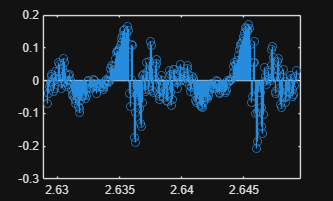


% indexing k
k = 42069;

% Extracting segment starting with k
x_segment = x(k: k + 319);
t_segment = t(k : k+319);

figure(2)
stem(t_segment, x_segment)